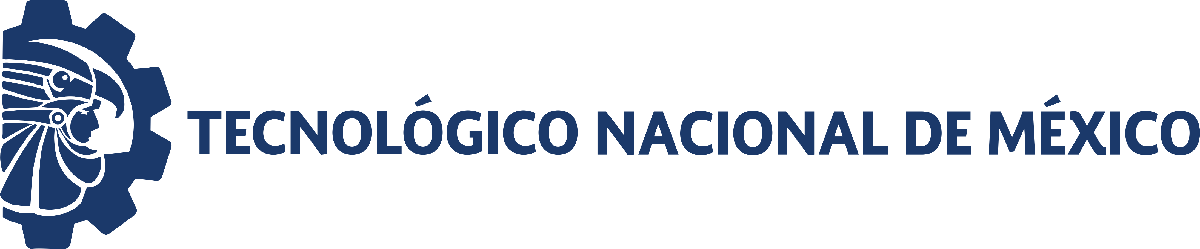                                 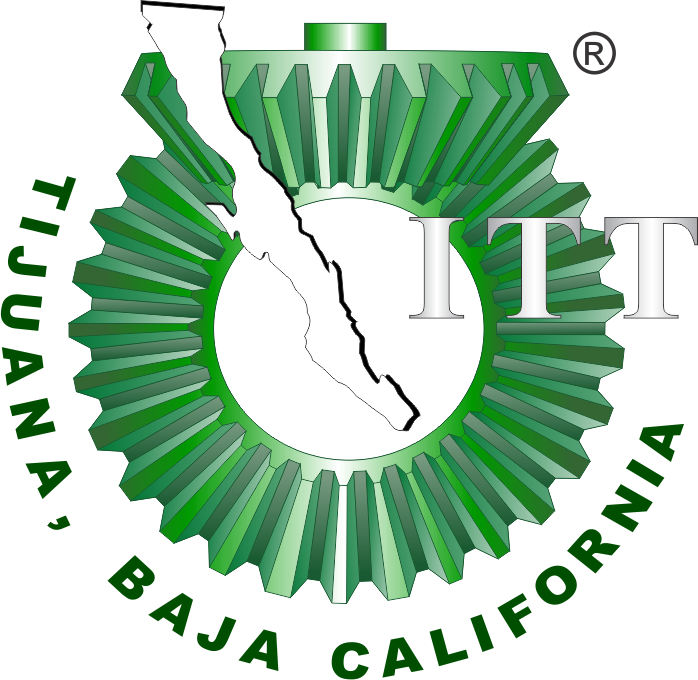

# Práctica 3: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: Maria Belen Galindo Ramirez                                                                 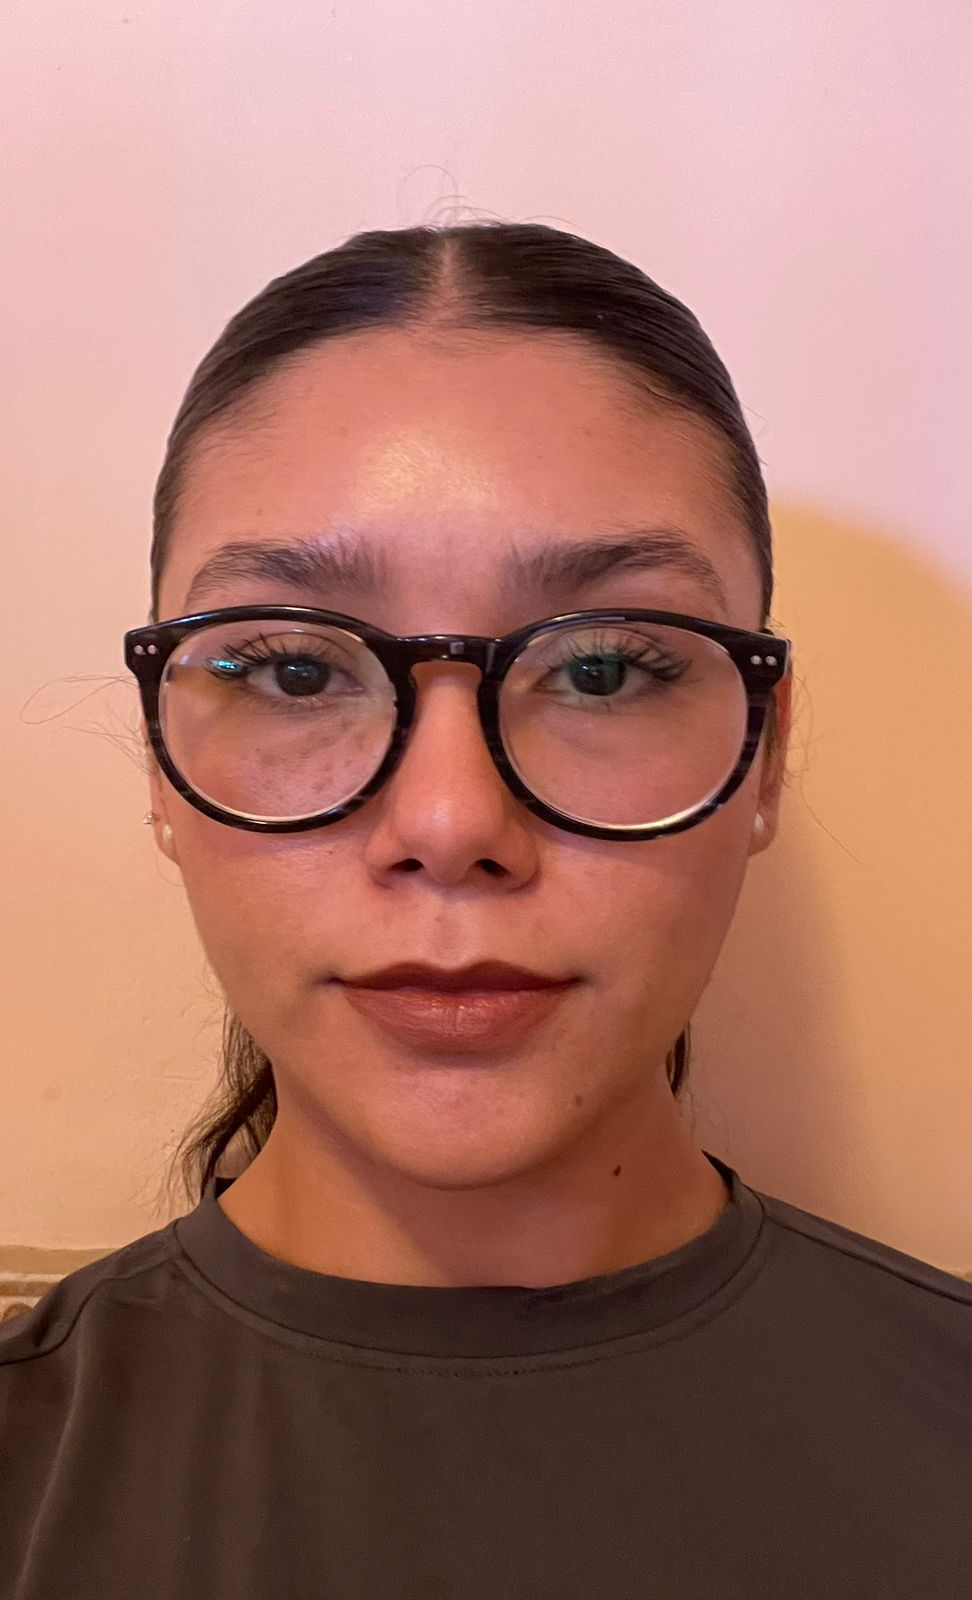

Número de control: 22211755

Correo institucional: l22211755**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación: Lazo cerrado

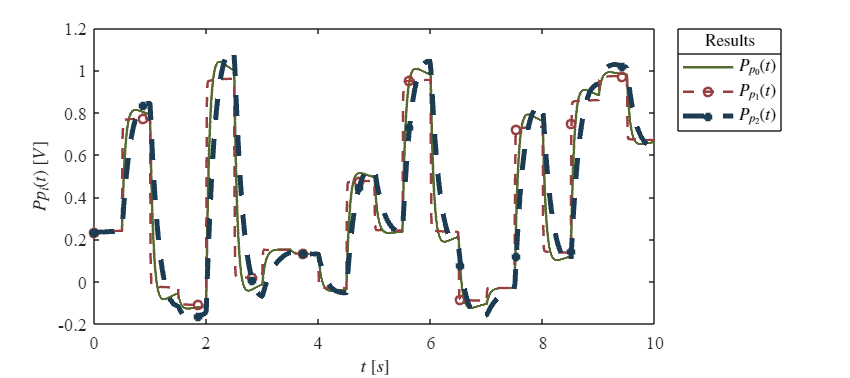

clc; clear; close all; warning('off','all')
tend = '10';
file = 'sistema';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('sistema/Ppa(t)','Minimum','-0.2');
set_param('sistema/Ppa(t)','Maximum','1');
set_param('sistema/Ppa(t)','Seed','106');
set_param('sistema/Ppa(t)','SampleTime','0.5');
x = sim(file,parameters);
writematrix(x.Ppa,'signal.xlsx')
plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,'grafica')

## Lazo abierto 

set_param('sistema/Ppa(t)','Minimum','-0.2');
set_param('sistema/Ppa(t)','Maximum','1');
set_param('sistema/Ppa(t)','Seed','106');
set_param('sistema/Ppa(t)','SampleTime','0.5');
x2 = sim(file,parameters);
plotsignals2(x2.t,x2.Pp0,x2.Pp1,x2.Pp2,'grafica')

## Función 1 

function plotsignals(t,Pp0,Pp1,Pp2,Pp3,Pp4, Signal)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [85,107,47;
            154,63,63;
            27,60,83;
            152,161,188;
            51,56,160;
            249,122,0]/255;
colororder(mycolors)

p =  plot(t,Pp0,'-',t,Pp1,'--O',t,Pp2,'--+',t,Pp3,'--x',t,Pp4,':',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(5),'LineWidth',3);
 L = legend('$P_{p_0}(t)$','$P_{p_1}(t)$','$P_{p_2}(t)$','$P_{p_3}(t)$','$P_{p_4}(t)$');
 set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');

title(L,'Results','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

 exportgraphics(gcf,[Signal,'_lazoCerrado.pdf'], 'ContentType','vector')
 exportgraphics(gcf,[Signal,'_lazoCerrado.png'], 'Resolution',300)

end



## Función 2 


function plotsignals2(t,Pp0,Pp1,Pp2,Signal)
set(figure(),'Color','w')
set(gcf,'units','centimeters','position',[1,1,18,8])
set(gca,'FontName','Times New Roman','FontSize',11)
hold on; grid off; box on;
mycolors = [85,107,47;
            154,63,63;
            27,60,83;
            152,161,188;
            51,56,160;
            249,122,0]/255;
colororder(mycolors)

p =  plot(t,Pp0,'-',t,Pp1,'--O',t,Pp2,'--+',...
     'LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
set(p(3),'LineWidth',3);
 L = legend('$P_{p_0}(t)$','$P_{p_1}(t)$','$P_{p_2}(t)$');
 set(L,'Interpreter','Latex','FontSize',10,'Location','BestOutside','Box','on');

title(L,'Results','FontSize',10)

 xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
 ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)

 exportgraphics(gcf,[Signal,'_lazoAbierto.pdf'], 'ContentType','vector')
 exportgraphics(gcf,[Signal,'_lazoAbierto.png'], 'Resolution',300)

end
